# DO Worked Example 

This example is provided by Kristen Fogaren (fogaren@bc.edu) on August 8, 2022. Thanks to Craig Risien (craig.risien@oregonstate.edu) for providing the code to directly pull netCDF files from THREDDS server. Pulled netCDF were converted to *.csv files and provided to allow for duplication of this worked example in any coding language. 

*Note: users will also need download the *[*Gibbs Sea Water Package*](https://www.teos-10.org/software.htm)* to add to current Matlab path *

#### Overview

Here, we provide end-users with an example that uses discrete, Winkler-titrated oxygen measurements to correct for the storage drift (with a gain correction) and deployment drift (with a drift correction) of an OOI-provided Level 2 oxygen product to produce an oxygen product for scientific use. The Level 2 oxygen product is oxygen timeseries data from an Aanderaa optode on the near-surface instrument frame on the Oregon Offshore Surface Mooring of the Coastal Endurance Array from April 2019 to July 2020. 

## Assemble data  

### [Quick look at oxygen data](https://dataexplorer.oceanobservatories.org/?ls=QD8vVnsP#data/4) available on Data Explorer and saved as Data View 

### Look at HITL and QARTOD annotations associated with oxygen and ancillary (temp, sal, pressure) parameters

- HITL annotations and QARTOD results for [oxygen data](https://dataexplorer.oceanobservatories.org/?ls=QD8vVnsP#metadata/103785/station/95/sensor/data?start=2019-04-05T20:51:40Z&end=2022-05-22T02:48:00Z&bin=days&leg_clim_upper_env=false&leg_clim_lower_env=false&leg_clim_mean=false&leg_clim_max=false&leg_clim_min=false) 

- HITL annotations and QARTOD results for[ temperature data](https://dataexplorer.oceanobservatories.org/?ls=QD8vVnsP#metadata/103784/station/7/sensor/data?start=2019-04-12T09:12:11Z&end=2022-05-23T01:45:00Z&bin=days&leg_minmax=false&leg_clim_max=false&leg_clim_min=false&leg_clim_mean=false&leg_clim_lower_env=false&leg_clim_upper_env=false)

- HITL annotations and QARTOD results for [salinity data](https://dataexplorer.oceanobservatories.org/?ls=QD8vVnsP#metadata/103784/station/14/sensor/data?start=2019-04-12T23:37:58Z&end=2022-05-23T01:45:00Z&bin=days&leg_minmax=false&leg_clim_max=false&leg_clim_min=false&leg_clim_mean=false&leg_clim_lower_env=false&leg_clim_upper_env=false)

- HITL annotations and QARTOD results for [pressure data](https://dataexplorer.oceanobservatories.org/?ls=QD8vVnsP#metadata/103784/station/87/sensor/data?start=2019-04-13T18:53:51Z&end=2022-05-23T01:45:00Z&bin=days&leg_minmax=false&leg_clim_max=false&leg_clim_min=false&leg_clim_mean=false&leg_clim_lower_env=false&leg_clim_upper_env=false)

RESULTS: 

- No oxygen annotations other than UV light installation date and brief power outages

- Target data is after the installation of anti-biofouling UV lights (April 2018)

- Note, no QARTOD tests are implemented at this time for oxygen data streams

- Some temp, salinity, pressure data is "suspect/of interest" but it is unclear which QARTOD tests have been executed on Data Explorer or from the netCDF files downloaded from THREDDS server

- THREDDS server will be updated Fall 2022 to include QARTOD tests executed for CTD parameters 

- **As such, QARTOD/QC results are not being used in this worked example** 

### Download discrete bottle summaries from Alfresco server

- [https://alfresco.oceanobservatories.org/](https://alfresco.oceanobservatories.org/)

- Find turn-around cruises that bookend deployments of interest (deployments 8 and 9)

- Endurance-11_SKQ201910S_OC1905C_Discrete_Summary.xlsx in [OOI](https://alfresco.oceanobservatories.org/alfresco/faces/jsp/browse/browse.jsp#) **> **Coastal Endurance Array** > **Cruise Data** > **Endurance-11a_SKQ201910S_2019-04** > **Ship_Data** > **Water Sampling

- Endurance-12_SKQ201921S_Discrete_Summary.xlsx in [OOI](https://alfresco.oceanobservatories.org/alfresco/faces/jsp/browse/browse.jsp#)** > **Coastal Endurance Array** > **Cruise Data** > **Endurance-12_SKQ201921S_2019-10** > **Ship_Data** > **Water Sampling

- Endurance-13_TN380_Discrete_Summary.xlsx in [OOI](https://alfresco.oceanobservatories.org/alfresco/faces/jsp/browse/browse.jsp#)** > **Coastal Endurance Array** > **Cruise Data** > **Endurance-13_TN380_2020-07** > **Ship_Data** > **Water Sampling

### Review discrete bottle summary annotations

Endurance 11, Endurance 12 and Endurance 13 

- All casts followed standard SOP

- All CTD Files were processed according to SOP

- No issues with discrete samples at station of interest, CE04

### Download Data

- This code uses local function to read in netCDFs directly from the THREDDS server and into data structures

- Reads in data for dissolved oxygen, salinity, temperature, pressure 

% Read in data from OOI THREDDS server and display netCDF information 
deployment8 = pull_DO_Data_from_THREDDS('deployment0008');
deployment9 = pull_DO_Data_from_THREDDS('deployment0009');

### Plot Data 

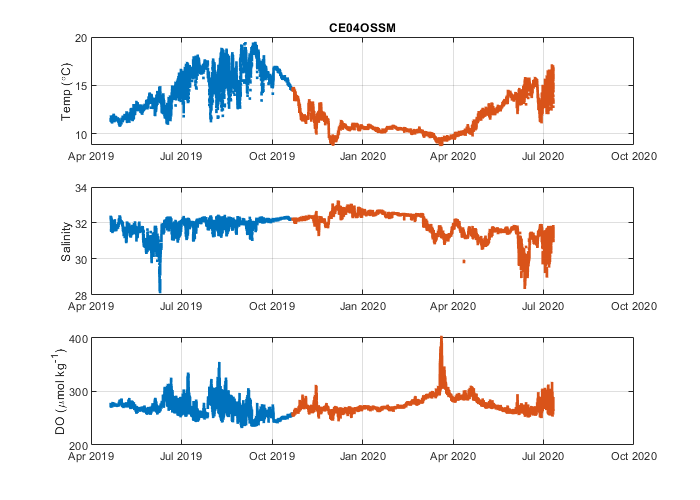

% Plot CTD/Anderra deployments by color 

f0 = figure;
f0.Position = [200 200 700 500];
ax1 = subplot(3,1,1);
plot(deployment8.CTDdt,deployment8.temp,'.')
hold on
plot(deployment9.CTDdt,deployment9.temp,'.')
ylabel('Temp (\circC)')
grid on
title('CE04OSSM')

ax2 = subplot(3,1,2);
plot(deployment8.CTDdt,deployment8.practical_salinity,'.')
hold on
plot(deployment9.CTDdt,deployment9.practical_salinity,'.')
ylabel('Salinity')
grid on

ax3 = subplot(3,1,3);
plot(deployment8.DOdt,deployment8.dissolved_oxygen,'.')
hold on
plot(deployment9.DOdt,deployment9.dissolved_oxygen,'.')
ylabel('DO (\mumol kg^-^1)')
grid on
linkaxes([ax3 ax2 ax1],'x')

- Noticable difference in downloaded dissolved oxygen data (consistent between deployments) and dissolved oxygen data on data explorer (offset between deployments, see jump ~ Oct 2019 below).

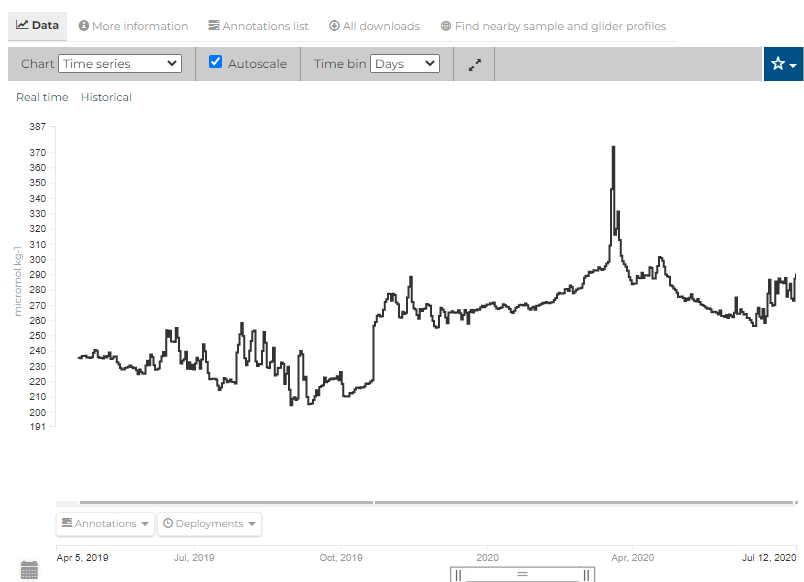

- Answer from Chris Wingard: There was a bug in the system where values from two-point calibrations were not being used in processing of oxygen data. This has been updated on the THREDDS server but it looks like Data Explorer has not updated the code it is using to reflect that change. He submitted a helpdesk ticket. 5-23-2022

### Calculate and plot median of 3-min DO burst sampling

- Aanderra sensor burst samples at 0.5 Hz for 3 minutes every 15 minutes

- The science idea behind 3 minute burst is it gives you enough data to average over a series of wave cycles, minimizing the impact of surface waves on the measurement

% Takes a while, inefficient loops, maybe because in structure? 
% calculates median for each burst 
% dissolved_oxygen_median needs CTDdt and not DOdt which includes all burst data 

deployment8.dissolved_oxygen_median = NaN(1,length(deployment8.CTDdt)); % Deployment 8 
for i = 1:length(deployment8.CTDdt)
    ts0 = deployment8.CTDdt(i);
    ts = find(deployment8.DOdt > ts0,1);
    deployment8.dissolved_oxygen_median(i) = median(deployment8.dissolved_oxygen(deployment8.DOdt < (deployment8.DOdt(ts) + minutes(3))...
    & deployment8.DOdt > deployment8.DOdt(ts)));
end

deployment9.dissolved_oxygen_median = NaN(1,length(deployment9.CTDdt)); % Deployment 9
for i = 1:length(deployment9.CTDdt)
    ts0 = deployment9.CTDdt(i);
    ts = find(deployment9.DOdt > ts0,1);
    deployment9.dissolved_oxygen_median(i) = median(deployment9.dissolved_oxygen(deployment9.DOdt < (deployment9.DOdt(ts) + minutes(3))...
    & deployment9.DOdt > deployment9.DOdt(ts)));
end

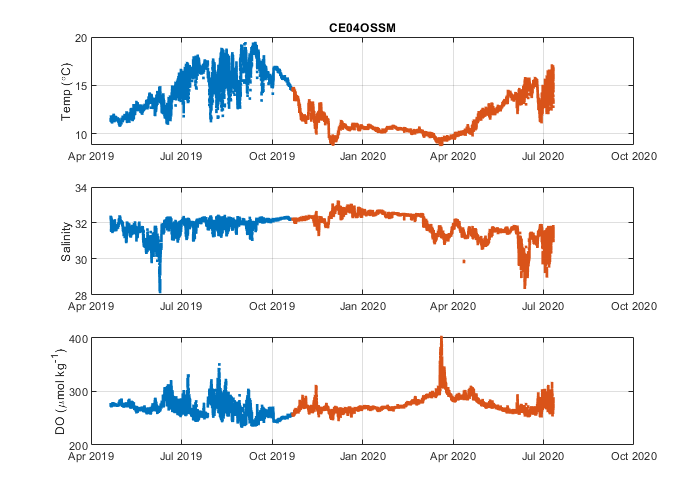

% Plot burst medians

f0 = figure;
f0.Position = [200 200 700 500];
ax1 = subplot(3,1,1);
plot(deployment8.CTDdt,deployment8.temp,'.')
hold on
plot(deployment9.CTDdt,deployment9.temp,'.')
ylabel('Temp (\circC)')
grid on
title('CE04OSSM')

ax2 = subplot(3,1,2);
plot(deployment8.CTDdt,deployment8.practical_salinity,'.')
hold on
plot(deployment9.CTDdt,deployment9.practical_salinity,'.')
ylabel('Salinity')
grid on

ax3 = subplot(3,1,3);
plot(deployment8.CTDdt,deployment8.dissolved_oxygen_median,'.')
hold on
plot(deployment9.CTDdt,deployment9.dissolved_oxygen_median,'.')
ylabel('DO (\mumol kg^-^1)')
grid on
linkaxes([ax3 ax2 ax1],'x')

### Compare to data from turn-around cruises

- Read in discrete bottle summaries and use local function (at end of script) to create water summary tables for site of interest 

- Plots show site of interest (CE04) and location of discrete samples for oxygen 

- Discrete water samples from Niskin bottles are measured for oxygen using Winkler titrations

- Temp and salinity data are from ship's CTD when Niksin bottles were fired 

- Plots showing discrete data with OOI datastreams 

% Set up workspace 
addpath('G:\My Drive\Matlab_work\Functions\GSW')
cd('G:\My Drive\Matlab_work\Github\ooi-bgc-cookbook\Oxygen')

% All Endurance turn-around cruises during deployments 8 and 9
% Files pulled from Alfresco 
CE11 = readtable('Endurance-11_SKQ201910S_OC1905C_Discrete_Summary.xlsx','TextType','string');

Error using readtable (line 245)
Unable to find or open 'Endurance-11_SKQ201910S_OC1905C_Discrete_Summary.xlsx'. Check the path and filename or file permissions.

CE12 = readtable('Endurance-12_SKQ201921S_Discrete_Summary.xlsx','TextType','string');
CE13 = readtable('Endurance-13_TN380_Discrete_Summary.xlsx','TextType','string');


showplots = 0; % 1 to display plots of CTD cast locations 
Station = 'CE04';

% Pull information for samples collected at Station == CE04
CE11CE04 = water_sample_table(CE11,Station,showplots);  %( Cruise, Station, Plot)
CE12CE04 = water_sample_table(CE12,Station,showplots); 
CE13CE04 = water_sample_table(CE13,Station,showplots); 

% Create table for discrete sample information at just site of interest, CE04
CE_CE04 = [CE11CE04; CE12CE04; CE13CE04]

% Pulls out discrete temp/sal/DO data around depth of Near surface insturment frame at 7 m 
ind = find(CE_CE04.CTDDepth_m > 6 & CE_CE04.CTDDepth_m < 10); % Greater than 6 but less than 10 m 
ind = ind(1:end-2); % remove last two points during deployment 10 that occured after removal of deployment 9 

f0 = figure;
f0.Position = [200 200 700 500];
ax1 = subplot(3,1,1);
plot(deployment8.CTDdt,deployment8.temp,'.')
hold on
plot(deployment9.CTDdt,deployment9.temp,'.')
plot(CE_CE04.CTDBottleClosureTime_UTC(ind),...
    CE_CE04.CTDTemperature1_degC(ind),'.k','MarkerSize',20)
axis tight
grid on
ylabel('Temp (\circC)')
title('CE02SHSM Temp','fontweight','normal')

ax2 = subplot(3,1,2);
plot(deployment8.CTDdt,deployment8.practical_salinity,'.')
hold on
plot(deployment9.CTDdt,deployment9.practical_salinity,'.')
plot(CE_CE04.CTDBottleClosureTime_UTC(ind),...
    CE_CE04.CTDSalinity1_psu(ind),'.k','MarkerSize',20)
axis tight
ylim([27 35])
grid on
ylabel('Salinity')
title('CE02SHSM Salinity','fontweight','normal')

ax3 = subplot(3,1,3);
plot(deployment8.CTDdt + minutes(1.5),deployment8.dissolved_oxygen_median,'.')
hold on
plot(deployment9.CTDdt + minutes(1.5),deployment9.dissolved_oxygen_median,'.')
plot(CE_CE04.CTDBottleClosureTime_UTC(ind),...
    CE_CE04.DiscreteOxygen_umolkg(ind),'.k','MarkerSize',20)
axis tight 
grid on
ylabel('DO (\mumol kg^-^1)')
linkaxes([ax3 ax2 ax1],'x')
title('CE04OSSM DO','fontweight','normal')


%% Take a closer look around turn-around cruises to check T/S from discrete samples match CTD on NSIF

for j = 1:2:length(ind) % by 2 because duplicate Winklers and only need 1 bottle closing time 
    f0 = figure;
    f0.Position = [200 200 700 500]; 
    ax1 = subplot(3,1,1);
    plot(deployment8.CTDdt,deployment8.temp,'.')
    hold on
    plot(deployment9.CTDdt,deployment9.temp,'.')
    plot(CE_CE04.CTDBottleClosureTime_UTC(ind),...
        CE_CE04.CTDTemperature1_degC(ind),'.k','MarkerSize',20)
    axis tight
    grid on
    ylabel('Temp (\circC)')
    title('CE02SHSM Temp')
    
    ax2 = subplot(3,1,2);
    plot(deployment8.CTDdt,deployment8.practical_salinity,'.')
    hold on
    plot(deployment9.CTDdt,deployment9.practical_salinity,'.')
    plot(CE_CE04.CTDBottleClosureTime_UTC(ind),...
        CE_CE04.CTDSalinity1_psu(ind),'.k','MarkerSize',20)
    axis tight
    ylim([27 35])
    grid on
    ylabel('Salinity')
    title('CE02SHSM Salinity')
    
    ax3 = subplot(3,1,3);
    plot(deployment8.CTDdt + minutes(1.5),deployment8.dissolved_oxygen_median,'.')
    hold on
    plot(deployment9.CTDdt + minutes(1.5),deployment9.dissolved_oxygen_median,'.')
    plot(CE_CE04.CTDBottleClosureTime_UTC(ind),...
        CE_CE04.DiscreteOxygen_umolkg(ind),'.k','MarkerSize',20)
    axis tight 
    grid on
    ylabel('DO (\mumol kg^-^1)')
    linkaxes([ax3 ax2 ax1],'x')
    xlim([CE_CE04.CTDBottleClosureTime_UTC(ind(j))-1 CE_CE04.CTDBottleClosureTime_UTC(ind(j))+1])
    title('CE04OSSM DO')
    sgtitle([CE_CE04.Cruise(ind(j))])
end

- Temperature and Salinity of CTD cast at time of bottle firing matches pretty well with Temp and salinity recorded by the deployed CTD

- Indicates that we can use the discrete Oxygen Samples to correct the deployed oxygen sensors

### Use Winklers to make gain correction and Plot Gain Corrected Data 

Gain = Winkler value/Sensor value

Gain corrected data = sensor value * gain value 

% Make table with just Winkler titrations of interest for depths and
% deployment times 
Winkler = CE_CE04(ind,:)
cruise = unique(Winkler.Cruise) % Find unique cruise names 
Wink_time = unique(Winkler.CTDBottleClosureTime_UTC)
% Look at mean and standard deviation of duplicate Winkler titrations 
Wink_Deploy8_start = nanmean([Winkler.DiscreteOxygen_umolkg(Winkler.Cruise == cruise(1))])
std = nanstd([Winkler.DiscreteOxygen_umolkg(Winkler.Cruise == cruise(1))])
Wink_Deploy8_end = nanmean([Winkler.DiscreteOxygen_umolkg(Winkler.Cruise == cruise(2))])
Wink_Deploy9_start = Wink_Deploy8_end
std = nanstd([Winkler.DiscreteOxygen_umolkg(Winkler.Cruise == cruise(2))])
Wink_Deploy9_end = nanmean([Winkler.DiscreteOxygen_umolkg(Winkler.Cruise == cruise(3))])
std = nanstd([Winkler.DiscreteOxygen_umolkg(Winkler.Cruise == cruise(3))])

% Compare to median DO value 
sensorDO_Deploy8_start = deployment8.dissolved_oxygen_median(find(deployment8.CTDdt > Wink_time(1),1))
sensorDO_Deploy9_start = deployment9.dissolved_oxygen_median(find(deployment9.CTDdt > Wink_time(2),1)) 



% Gain = Winkler value/Sensor value
gain8 = Wink_Deploy8_start/sensorDO_Deploy8_start
gain9 = Wink_Deploy9_start/sensorDO_Deploy9_start

% Adjust deployments for storage gain 
% Gain corrected data = sensor value * gain value
deploy8gain = deployment8.dissolved_oxygen_median*gain8;
deploy9gain = deployment9.dissolved_oxygen_median*gain9;  

% Plot gain corrected data
f0 = figure;
f0.Position = [200 200 700 500];
plot(deployment8.CTDdt + minutes(1.5),deployment8.dissolved_oxygen_median,'.')
hold on
plot(deployment9.CTDdt + minutes(1.5),deployment9.dissolved_oxygen_median,'.')
plot(deployment8.CTDdt + minutes(1.5),deploy8gain,'.')
hold on
plot(deployment9.CTDdt + minutes(1.5),deploy9gain,'.')
plot(CE_CE04.CTDBottleClosureTime_UTC(ind),...
    CE_CE04.DiscreteOxygen_umolkg(ind),'.k','MarkerSize',20)
axis tight 
grid on
ylabel('DO (\mumol kg^-^1)')
legend('Uncorrected','Uncorrected','Gain Corrected','Gain Corrected','Winkler','Location','NW')
title('Gain Corrected CE04OSSM DO','fontweight','bold')

### Calculate In situ Drift Correction 

In situ drift correction = Linearly interpolated correction between winkler value/sensor value at deployment time and winkler value/sensor value at recovery time

% Calculate in situ drift correction for Deployment 8
x8 = [Wink_time(1); Wink_time(2)]; 
y8 = [1; Wink_Deploy8_end/(deploy8gain(end))]; % in situ adjustment 1 to Winkler/sensor(already adjusted for gain)

% Find drift correction at each timepoint between Winkler samples 
deploy8drift = interp1(x8,y8,deployment8.CTDdt); % Interp in situ drift correction for deployment 8 times

% Set drift correction to each timepoint before Winkler Sample to no drift
deploy8drift(isnan(deploy8drift)) = 1; % Assumes brief period of Aanderra data before Winkler has no drift

% Calculate in situ drift correction for Deployment 9
% Find DO median time at Collection of end of Deployment 9 Winklers
sensorDO_Deploy9_end = deploy9gain(find(deployment9.CTDdt > Wink_time(3),1));

x9 = [Wink_time(2); Wink_time(3)]; 
y9 = [1; Wink_Deploy9_end/sensorDO_Deploy9_end]; % in situ adjustment 1 to Winkler/sensor(already adjusted for gain)

% Find drift correction at each timepoint between Winkler samples 
deploy9drift = interp1(x9,y9,deployment9.CTDdt); % Interp in situ drift correction for deployment 8 times 

% Set drift correction before deployment Winkler to 1
deploy9drift(1:8) = 1;
% Set drift correction after recovery Winkler to last same drift as last
% value 
deploy9drift(end-38:end) = Wink_Deploy9_end/sensorDO_Deploy9_end;

### Calculate final corrected oxygen and Plot Data 

DO corrected = sensor DO * gain correction * timeseries of drift correction

% Calculate corrected oxygen by deployment
% DO corrected = sensor DO * gain correction * timeseries of drift correction
deployment8.deploy8corrected = deploy8gain.*deploy8drift'; 
deployment9.deploy9corrected = deploy9gain.*deploy9drift'; 

% Plot gain corrected and drift corrected data
f0 = figure;
f0.Position = [200 200 700 500];
plot(deployment8.CTDdt + minutes(1.5),deployment8.dissolved_oxygen_median,'.')
hold on
plot(deployment9.CTDdt + minutes(1.5),deployment9.dissolved_oxygen_median,'.')
plot(deployment8.CTDdt + minutes(1.5),deployment8.deploy8corrected,'.')
hold on
plot(deployment9.CTDdt + minutes(1.5),deployment9.deploy9corrected,'.')
plot(CE_CE04.CTDBottleClosureTime_UTC(ind),...
    CE_CE04.DiscreteOxygen_umolkg(ind),'.k','MarkerSize',20)
axis tight 
grid on
ylabel('DO (\mumol kg^-^1)')
legend('Uncorrected','Uncorrected','Gain + Drift Corrected','Gain + Drift Corrected','Winkler','Location','NW')
title('Gain and Drift Corrected CE04OSSM DO','fontweight','bold')

### Make the finalized pretty plot  

blue = [0     0.44706     0.74118];
red = [0.85098     0.32549    0.098039];
grey = [0.65098     0.65098     0.65098];

f0 = figure;
f0.Position = [200 200 700 500];
subplot(2,1,1)
f = gca;
plot(deployment8.CTDdt + minutes(1.5),deployment8.dissolved_oxygen_median,'Color',blue,'Linewidth',1.4)
hold on
plot(deployment9.CTDdt + minutes(1.5),deployment9.dissolved_oxygen_median,'Color',red,'Linewidth',1.4)
plot(deployment8.CTDdt + minutes(1.5),deployment8.deploy8corrected,'Color',grey,'Linewidth',1.4)
plot(CE_CE04.CTDBottleClosureTime_UTC(CE_CE04.CTDDepth_m > 5 & CE_CE04.CTDDepth_m < 10),...
    CE_CE04.DiscreteOxygen_umolkg(CE_CE04.CTDDepth_m > 5 & CE_CE04.CTDDepth_m < 10),'.k','MarkerSize',20)
plot(deployment9.CTDdt + minutes(1.5),deployment9.deploy9corrected,'Color',grey)
plot(CE_CE04.CTDBottleClosureTime_UTC(CE_CE04.CTDDepth_m > 5 & CE_CE04.CTDDepth_m < 10),...
    CE_CE04.DiscreteOxygen_umolkg(CE_CE04.CTDDepth_m > 5 & CE_CE04.CTDDepth_m < 10),'.k','MarkerSize',20)
axis tight 
f.FontSize =13; 
ylabel('DO (\mumol kg^-^1)')
title({['Oregon Offshore Surface Mooring'] 'Near-surface instrument frame'})

subplot(2,1,2)
f = gca;
plot(deployment8.CTDdt + minutes(1.5),deployment8.dissolved_oxygen_median,'Color',blue,'Linewidth',1.4)
hold on
plot(deployment9.CTDdt + minutes(1.5),deployment9.dissolved_oxygen_median,'Color',red,'Linewidth',1.4)
plot(deployment8.CTDdt + minutes(1.5),deployment8.deploy8corrected,'Color',grey,'Linewidth',1.4)
plot(CE_CE04.CTDBottleClosureTime_UTC(CE_CE04.CTDDepth_m > 5 & CE_CE04.CTDDepth_m < 10),...
    CE_CE04.DiscreteOxygen_umolkg(CE_CE04.CTDDepth_m > 5 & CE_CE04.CTDDepth_m < 10),'.k','MarkerSize',20)
plot(deployment9.CTDdt + minutes(1.5),deployment9.deploy9corrected,'Color',grey,'Linewidth',1.4)
plot(CE_CE04.CTDBottleClosureTime_UTC(CE_CE04.CTDDepth_m > 5 & CE_CE04.CTDDepth_m < 10),...
    CE_CE04.DiscreteOxygen_umolkg(CE_CE04.CTDDepth_m > 5 & CE_CE04.CTDDepth_m < 10),'.k','MarkerSize',20)
ylim([220 270]) 
xlim([datetime(2019,10,20,'TimeZone','UTC') datetime(2019,10,24,'TimeZone','UTC')])
f.FontSize =13; 
ylabel('DO (\mumol kg^-^1)')
legend('Deployment 8','Deployment 9','Corrected','Winkler','Location','southoutside',"Orientation",'horizontal')

% Export data on finalized plots as csv 
writetable(Winkler,'Winkler.csv','Delimiter',',')

Deploy8Table = table(deployment8.CTDdt + minutes(1.5),deployment8.dissolved_oxygen_median',deployment8.deploy8corrected',...
    'VariableNames',{'datetime','oxygen_uncorrected_umol_kg','oxygen_corrected_umol_kg'});
Deploy9Table = table(deployment9.CTDdt + minutes(1.5),deployment9.dissolved_oxygen_median',deployment9.deploy9corrected',...
    'VariableNames',{'datetime','oxygen_uncorrected_umol_kg','oxygen_corrected_umol_kg'});

writetable(Deploy8Table,'Deploy8File.csv','Delimiter',',')
writetable(Deploy9Table,'Deploy9File.csv','Delimiter',',')


% Export median oxygen data, gain corrected oxygen data, and final (gain + drift
% corrected) oxygen data for worked-example checkpoints 
Deployment8Outputs = table(deployment8.CTDdt,deployment8.dissolved_oxygen_median',deploy8gain',deployment8.deploy8corrected',...
    'VariableNames',{'datetime','DO_median_umol_kg','DO_gain_corrected_umol_kg','DO_gain_drift_corrected_umol_kg'});

Deployment9Outputs = table(deployment9.CTDdt,deployment9.dissolved_oxygen_median',deploy9gain',deployment9.deploy9corrected',...
    'VariableNames',{'datetime','DO_median_umol_kg','DO_gain_corrected_umol_kg','DO_gain_drift_corrected_umol_kg'});


writetable(Deployment8Outputs,'Deployment8_Outputs.csv','Delimiter',',')
writetable(Deployment9Outputs,'Deployment9_Outputs.csv','Delimiter',',')


Localized functions below 

function deployment = pull_DO_Data_from_THREDDS(deploy_num)
%   deploy_num = 'deployment0012' % string of deployment you want 
options = weboptions('Timeout', 600);

site = 'CE04OSSM-RID27-04-DOSTAD000-recovered_host-dosta_abcdjm_dcl_instrument_recovered';
base_catalog_url = 'https://thredds.dataexplorer.oceanobservatories.org/thredds/catalog/ooigoldcopy/public/';

catalog = webread(strcat(base_catalog_url,site,'/catalog.html'),options);
nclist = regexp(catalog,'<a href=''([^>]+.nc)''>','tokens');
base_url = 'https://thredds.dataexplorer.oceanobservatories.org/thredds/dodsC/';

[~, ind] = find(contains(string(nclist),deploy_num) == 1);
    CTDind = ind(1); % CTD listed first
    DOSTAind = ind(2); % DOSTA listed second 

% For first file : CTD
CTD_url_thredds = nclist{1,CTDind}{1,1}; 
CTD_url_thredds = strcat(base_url,CTD_url_thredds(22:end),'#fillmismatch');
% ncdisp(CTD_url_thredds) % Displays all info for variables in netCDF

% For second file: DOSTA
DOSTA_url_thredds = nclist{1,DOSTAind}{1,1}; 
DOSTA_url_thredds = strcat(base_url,DOSTA_url_thredds(22:end),'#fillmismatch');
% ncdisp(DOSTA_url_thredds) % Displays all info for variables in netCDF

time = ncread(CTD_url_thredds,'time');
deployment.CTDdn = datenum(1900,1,1,0,0,0)+(time/60/60/24);
deployment.CTDdt = datetime(deployment.CTDdn,'ConvertFrom','datenum','TimeZone','UTC'); clear time
deployment.pressure_qartod_executed = ncread(CTD_url_thredds,'pressure_qartod_executed');
deployment.pressure_qartod_results = ncread(CTD_url_thredds,'pressure_qartod_results');
deployment.pressure = ncread(CTD_url_thredds,'pressure');
deployment.temp_qartod_executed = ncread(CTD_url_thredds,'temp_qartod_executed');
deployment.temp_qartod_results = ncread(CTD_url_thredds,'temp_qartod_results');
deployment.temp = ncread(CTD_url_thredds,'temp');
deployment.practical_salinity = ncread(CTD_url_thredds,'practical_salinity');
deployment.practical_salinity_qartod_executed = ncread(CTD_url_thredds,'practical_salinity_qartod_executed');
deployment.practical_salinity_qartod_results = ncread(CTD_url_thredds,'practical_salinity_qartod_results');
deployment.depth = ncread(CTD_url_thredds,'depth');
deployment.deployment = ncread(CTD_url_thredds,'deployment');

time = ncread(DOSTA_url_thredds,'time');
deployment.DOdn = datenum(1900,1,1,0,0,0)+(time/60/60/24);
deployment.DOdt = datetime(deployment.DOdn,'ConvertFrom','datenum','TimeZone','UTC'); clear time
deployment.dissolved_oxygen_qc_executed = ncread(DOSTA_url_thredds,'dissolved_oxygen_qc_executed');
deployment.dissolved_oxygen_qc_results = ncread(DOSTA_url_thredds,'dissolved_oxygen_qc_results');
deployment.dissolved_oxygen = ncread(DOSTA_url_thredds,'dissolved_oxygen');
deployment.lat = ncreadatt(DOSTA_url_thredds,'/','lat');
deployment.lon = ncreadatt(DOSTA_url_thredds,'/','lon');

end

function [DS] = water_sample_table(cruise,Station,showplots) 
DS = table(cruise.Cruise(cruise.Station == Station), cruise.Station(cruise.Station == Station), cruise.Cast(cruise.Station == Station), cruise.Niskin_BottlePosition(cruise.Station == Station),...
    cruise.CTDLatitude_deg_(cruise.Station == Station),cruise.CTDLongitude_deg_(cruise.Station == Station),cruise.CTDPressure_db_(cruise.Station == Station),...
    cruise.CTDBottleClosureTime_UTC_(cruise.Station == Station),cruise.CTDDepth_m_(cruise.Station == Station), cruise.CTDTemperature1_degC_(cruise.Station == Station),...
    cruise.CTDSalinity1_psu_(cruise.Station == Station), cruise.CTDOxygen_mL_L_(cruise.Station == Station), double(cruise.DiscreteOxygen_mL_L_(cruise.Station == Station)),...
    'VariableNames',{'Cruise','Station','Cast','Niskin_BottlePosition','CTDLatitude_deg','CTDLongitude_deg','CTDPressure_db','CTDBottleClosureTime_UTC',...
    'CTDDepth_m','CTDTemperature1_degC','CTDSalinity1_psu','CTDOxygen_mL_L','DiscreteOxygen_mL_L'});

DS.CTDBottleClosureTime_UTC = datetime(DS.CTDBottleClosureTime_UTC,'InputFormat','yyyy-MM-dd''T''HH:mm:ss.SSSZ','TimeZone','UTC');

DS.DiscreteOxygen_mL_L(DS.DiscreteOxygen_mL_L == -9999999) = NaN; % Replaces flag for missing data with NaN
DS.DiscreteOxygen_umolL = double(DS.DiscreteOxygen_mL_L)*44.661; % convert from ml/l to umol/l

% Code taken from OOI Github 
pref = 0; % Reference pressure (db)
SA = gsw_SA_from_SP(DS.CTDSalinity1_psu, DS.CTDPressure_db, DS.CTDLongitude_deg, DS.CTDLatitude_deg);
CT = gsw_CT_from_t(SA, DS.CTDTemperature1_degC, DS.CTDPressure_db);
pdens = gsw_rho(SA, CT, pref); % potential referenced to p=0

% Convert from volume to mass units:
DS.DiscreteOxygen_umolkg = 1000*DS.DiscreteOxygen_umolL./pdens;
DS.CTDOxygen_umolkg = 1000*DS.CTDOxygen_mL_L*44.661./pdens;

% Location of Oregon Shelf Offshore Surface Mooring 
CE04OSSM = [44.37868, -124.94508]; % From OOI Website
dn = datenum(mean(DS.CTDBottleClosureTime_UTC,'omitnan')); % For Figure title 

    if showplots == 1
        figure
        plot(CE04OSSM(2),CE04OSSM(1),'.k','MarkerSize',30)
        hold on
        plot(DS.CTDLongitude_deg,DS.CTDLatitude_deg,'*','MarkerSize',10)
        title([Station ': ' datestr(dn,'mmmm yyyy')])
        grid on
        legend('CE04','Cast w/ DO','Location','northeastoutside')
        
        casts = unique(DS.Cast);
        for i = 1:length(casts)
            text(DS.CTDLongitude_deg(DS.Cast == casts(i)),DS.CTDLatitude_deg(DS.Cast == casts(i)),{casts(i)})
        end
    end
end
